## A tutorial for the improved Loewner Framework for modal analysis

The Loewner Framework was extended to modal parameters identification from mechanical systems in [3-5] with its main limitation being a single-input multi-output method. In this tutorial, a computationally improved version of the LF, the iLF, extending the LF capability to multi-input multi-output (MIMO), is presented with the scope of guiding the reader to its use.

The code has been developed in MATLAB R2021b, it is not guaranteed to work in earlier versions of the software. Note that if you are on a MATLAB version lower than R2020a you might have trouble with the tiledlayout legend in this tutorial.

When using this, or part of, tutorial release, please always cite the following:

[1] G. Dessena and M. Civera, 'Improved Tangential Interpolation-based Multi-input Multi-output Modal Analysis of a Full Aircraft', *preprint*, 2024, doi: [10.48550/arXiv.2408.03810](https://arxiv.org/abs/2408.03810).

[2] G. Dessena, M. Civera, L. Zanotti Fragonara, D. I. Ignatyev, and J. F. Whidborne, ‘A Loewner-Based System Identification and Structural Health Monitoring Approach for Mechanical Systems’, Structural Control and Health Monitoring, vol. 2023. Hindawi Limited, pp. 1–22, Apr. 18, 2023. doi: [10.1155/2023/1891062](https://onlinelibrary.wiley.com/doi/10.1155/2023/1891062).

[3] G. Dessena, 'A tutorial for the improved Loewner Framework for modal analysis', Software, Universidad Carlos III de Madrid, 2024. doi: [10.5281/zenodo.13863292](https://doi.org/10.5281/zenodo.13863292). Available at: [https://zenodo.org/records/zenodo.13863292](https://zenodo.org/records/zenodo.13863292).

### The Model

The model is a sample system provided with MATLAB releases and consists of a two-input/three-output system excited by several bursts of random noise (see Figure 1). Each burst lasts for 1 second, and there are 2 seconds between the end of each burst and the start of the next. The data is sampled at 4 kHz.

See below for the time histories and FRFs of the system.

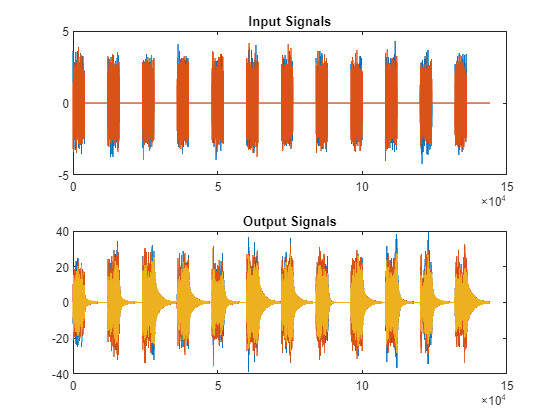

clear all
close all

load modaldata

subplot(2,1,1)
plot(Xburst)
title('Input Signals')
subplot(2,1,2)
plot(Yburst)
title('Output Signals')

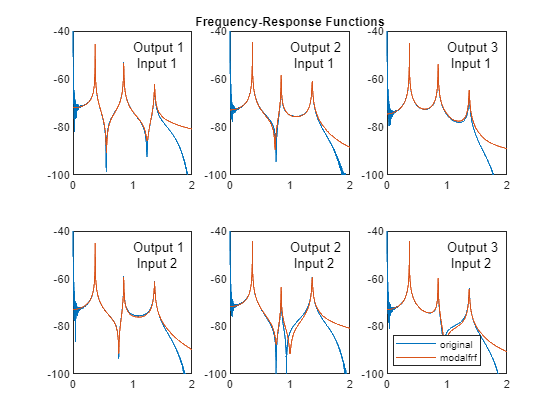

burstLen = 12000;
[frf,f] = modalfrf(Xburst,Yburst,fs,burstLen);


phfr = [373 852 1371];

[fn,dr,ms,ofrf] = modalfit(frf,f,fs,6,'PhysFreq',phfr);

for k = 1:2
    for m = 1:3
        subplot(2,3,m+3*(k-1))
        plot(f/1000,10*log10(abs(frf(:,m,k))))
        hold on
        plot(f/1000,10*log10(abs(ofrf(:,m,k))))
        hold off
        text(1,-50,[['Output ';' Input '] num2str([m k]')])
        ylim([-100 -40])
        if k ==2 & m==3
            legend({'original','modalfrf'},"Location","southwest")
        end
    end
end
subplot(2,3,2)
title('Frequency-Response Functions')

Here the iLF with MIMO capability is implemented on the system above. The iLF ability to deal with missing data is used to avoid the drift at lower frequency shown in the FRF plots. For the interpolation *f* > 100Hz are considered.

si = f*complex(0,1);
for i =1:max(size(ofrf))
    Hi(:,:,i) =  squeeze(ofrf(i,:,:));
end
tic
[id,model,fit] = iLF_id(Hi(:,:,301:2:end),si(301:2:end),6);
t=toc; 
disp(string(t)+" s on MATLAB R2021b - Windows 10 - 128 GB DDR4 RAM - 16-core Intel(R) Xeon(R) CPU E5-2698 v3 @ 2.30GHz") 

3.9684 s on MATLAB R2021b - Windows 10 - 128 GB DDR4 RAM - 16-core Intel(R) Xeon(R) CPU E5-2698 v3 @ 2.30GHz


Let's now plot the iLF-fitted model against the original FRF:

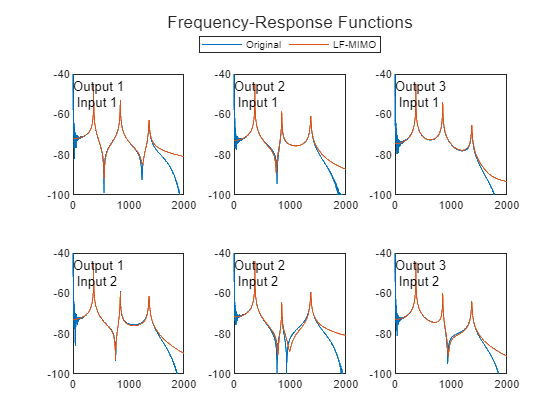

for i = 1:length(si)
        FRF_fit(:,:,i) = model.C*( (si(i).*model.E-model.A)\model.B);
end

figure
tl = tiledlayout(2,3);
for k = 1:2
    for m = 1:3
        nexttile
        plot(abs(si),10*log10(abs(frf(:,m,k))))
        hold on
        plot(abs(si),10*log10(abs(squeeze(FRF_fit(m,k,:)))))
        hold off
        text(1,-50,[['Output ';' Input '] num2str([m k]')])
        ylim([-100 -40])
    end
end
leg = legend({'Original', 'LF-MIMO'},'Location','northoutside','Orientation','horizontal');
title(tl,'Frequency-Response Functions')
leg.Layout.Tile = 'north';

### Modal parameters Comparison

The expected modal parameters (first row - $\bf{\omega}_n$, second row - $\bf{\zeta}_n$, third to last row - $\bf{\phi}_n$) are the following:

mod=abs(modalParams.hammerMISO.ms0);                             %Modal shape normalisation
mod=mod./max(mod,[],1);
ph=angle(modalParams.hammerMISO.ms0);
ph1=ph - ph(1,:);
ms0=mod.*sign(cos(ph1));
vpa([modalParams.hammerMISO.fn0';modalParams.hammerMISO.dr0'; ms0],7)

$$ans = \left(\begin{array}{ccc} 372.6801 & 852.5041 & 1370.57\\ 0.000780824 & 0.001785605 & 0.002870592\\ 0.8469745 & 1.0 & 0.6384277\\ 1.0 & 0.2523416 & -1.0\\ 0.9336985 & -0.7849187 & 0.3279202 \end{array}\right)$$

The modal parameter identified via modalfit - standard option is least squares complex exponential (LSCE):

mod=abs(ms);                             %Modal shape normalisation
mod=mod./max(mod,[],1);
ph=angle(ms);
ph1=ph - ph(1,:);
mod.*sign(cos(ph1));
vpa([fn'; dr'; mod.*sign(cos(ph1))],7)

$$ans = \left(\begin{array}{ccc} 372.6797 & 852.51 & 1370.56\\ 0.0007898842 & 0.001788482 & 0.002863741\\ 0.8539813 & 1.0 & 0.7205156\\ 1.0 & 0.2996384 & -1.0\\ 0.9452163 & -0.8566122 & 0.4397303 \end{array}\right)$$

Lastly, those identified via iLF are:

vpa(id.ident,7)

$$ans = \left(\begin{array}{ccc} 372.6797 & 852.5096 & 1370.562\\ 0.0007898458 & 0.001788817 & 0.002862365\\ 0.8502998 & 1.0 & 0.6535707\\ 1.0 & 0.2924284 & -1.0\\ 0.9379627 & -0.8496108 & 0.3439804 \end{array}\right)$$

Let's take a look at the error, in percentage, for $\bf{\omega}_n$ and $\bf{\zeta}_n$ wrt to the expected data:

Dw_n = 100*(id.ident(1,:)-modalParams.hammerMISO.fn0')./modalParams.hammerMISO.fn0';
vpa(Dw_n,5) % Natural Frequency error in %

$$ans = \left(\begin{array}{ccc} -0.000088517 & 0.00064676 & -0.00059298 \end{array}\right)$$

Dz_n = 100*(id.ident(2,:)-modalParams.hammerMISO.dr0')./modalParams.hammerMISO.dr0';
vpa(Dz_n,5) % Modal Damping Ratios error in %

$$ans = \left(\begin{array}{ccc} 1.1554 & 0.17987 & -0.28662 \end{array}\right)$$

Now lets plot the iLF identified $\bf{\phi}_n$ versus those expected:

figure
t,tiledlayout(1,3)

t = 3.9684

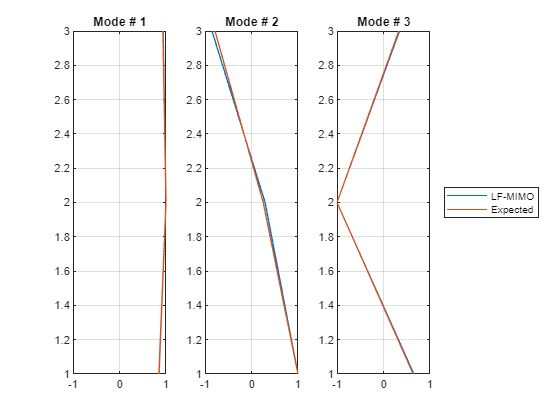

for i = 1:3
    nexttile
    lf = plot(id.ident(3:end,i),1:3);
    hold on
    ef = plot(ms0(:,i),1:3);
    hold off
    xlim([-1 1]);
    ylim([1 3]);
    title('Mode # '+string(i));
    grid on
end
    legend([lf,ef],{'LF-MIMO','Expected'},Location="eastoutside")

We can graphically see they are very similar. Let's confirm this by calculating the Modal Assurance Criterion (MAC) between the expected $\bf{\phi}_n$ and those identified via iLF:

vpa(round(compute_mac(ms0,id.ident(3:end,:)),3),3)

$$ans = \left(\begin{array}{ccc} 1.0 & 0.026 & 0.004\\ 0.031 & 0.998 & 0.007\\ 0.006 & 0.002 & 1.0 \end{array}\right)$$

Hence, the great coherence between the expected and iLF-identified $\bf{\phi}_n$ is confirmed as the values on the MAC matrix diagonal are, or very close to, 1.

### Conclusions

This example shows the accuracy of the iLF on a simple MIMO system. For the results obtained for more complex system the reader is reffered to the article accompained by this tutorial [1].

### References

[1] G. Dessena and M. Civera, 'Improved Tangential Interpolation-based Multi-input Multi-output Modal Analysis of a Full Aircraft', *preprint*, 2024, doi: [10.48550/arXiv.2408.03810](https://arxiv.org/abs/2408.03810).

[2] G. Dessena, 'A tutorial for the improved Loewner Framework for modal analysis', Software, Universidad Carlos III de Madrid, 2024. [10.5281/zenodo.13863292](https://doi.org/10.5281/zenodo.13863292). Available at: [https://zenodo.org/records/zenodo.13863292](https://zenodo.org/records/zenodo.13863292).

[3] G. Dessena, M. Civera, L. Zanotti Fragonara, D. I. Ignatyev, and J. F. Whidborne, ‘A Loewner-Based System Identification and Structural Health Monitoring Approach for Mechanical Systems’, Structural Control and Health Monitoring, vol. 2023. Hindawi Limited, pp. 1–22, Apr. 18, 2023. doi: [10.1155/2023/1891062](https://onlinelibrary.wiley.com/doi/10.1155/2023/1891062).

[4] G. Dessena, M. Civera, D. I. Ignatyev, J. F. Whidborne, L. Zanotti Fragonara, and B. Chiaia, ‘The Accuracy and Computational Efficiency of the Loewner Framework for the System Identification of Mechanical Systems’, Aerospace, vol. 10, no. 6. MDPI AG, p. 571, Jun. 20, 2023. doi: [10.3390/aerospace10060571](https://www.mdpi.com/2226-4310/10/6/571).

[5] G. Dessena, M. Civera, A. Pontillo, D. I. Ignatyev, J. F. Whidborne, and L. Zanotti Fragonara, ‘Noise-robust Modal Parameter Identification and Damage Assessment for Aero-structures’, Aircraft Engineering and Aerospace Technology, Aug. 2024. doi: [10.1108/AEAT-06-2024-0178](https://doi.org/10.1108/AEAT-06-2024-0178).